# Chapter 5 Exercises

#### Exercise 25

Consider the following boundary value problem


$$y'' = 2t, \qquad y(0) = 1, \qquad y(2) = 3.$$


Using a pen and calculator, calculate the Euler method solutions using a step length of $h=0.4$ and guess values of $y'(0) = 1$ and $y'(0) = -1$.

% Define ODE
f = @(t, y) [y(2), 2 * t];

% Define exact solution
exact = @(t) 1 / 3 * t .^ 3 - 1 / 3 * t + 1;

% Define BVP
tspan = [0, 2];
bvals = [1, 3];
h = 0.4;
s1 = 1;
s2 = -1;

% Solve IVP using the Euler method and s = 1
[t, y1] = euler(f, tspan, [bvals(1), s1], h);

% Print table of solution values (for loop is used to group print statements)
for i = 1 : 1
    fprintf("|  t   |    y1     |    y2     |")
    fprintf("|:----:|:---------:|:---------:|");
    for n = 1 : length(t)
        fprintf("\n| %4.2f | %9.6f | %9.6f |", t(n), y1(n,1), y1(n,2));
    end
end

|  t   |    y1     |    y2     |

|:----:|:---------:|:---------:|


| 0.00 |  1.000000 |  1.000000 |
| 0.40 |  1.400000 |  1.000000 |
| 0.80 |  1.800000 |  1.320000 |
| 1.20 |  2.328000 |  1.960000 |
| 1.60 |  3.112000 |  2.920000 |
| 2.00 |  4.280000 |  4.200000 |

% Solve IVP using the Euler method and s = -1
[t, y2] = euler(f, tspan, [bvals(1), s2], h);

% Print table of solution values (for loop is used to group print statements)
for i = 1 : 1
    fprintf("|  t   |    y1     |    y2     |")
    fprintf("|:----:|:---------:|:---------:|");
    for n = 1 : length(t)
        fprintf("\n| %4.2f | %9.6f | %9.6f |", t(n), y2(n,1), y2(n,2));
    end
end

|  t   |    y1     |    y2     |

|:----:|:---------:|:---------:|


| 0.00 |  1.000000 | -1.000000 |
| 0.40 |  0.600000 | -1.000000 |
| 0.80 |  0.200000 | -0.680000 |
| 1.20 | -0.072000 | -0.040000 |
| 1.60 | -0.088000 |  0.920000 |
| 2.00 |  0.280000 |  2.200000 |

#### Exercise 26

Use the Secant method to calculate the next value of $s$ for your solutions to the boundary value problem in exercise 24 and hence calculate the Euler method using this new guess value.

s3 = s2 - (bvals(2) - y2(end,1)) * (s2 - s1) / ((bvals(2) - y2(end,1)) - (bvals(2) - y1(end,1)));

% Solve IVP using the Euler method and s = -1
[t, y3] = euler(f, tspan, [bvals(1), s3], h);

% Print table of solution values (for loop is used to group print statements)
for i = 1 : 1
    fprintf("|  t   |    y1     |    y2     |")
    fprintf("|:----:|:---------:|:---------:|");
    for n = 1 : length(t)
        fprintf("\n| %4.2f | %9.6f | %9.6f |", t(n), y3(n,1), y3(n,2));
    end
end

|  t   |    y1     |    y2     |

|:----:|:---------:|:---------:|


| 0.00 |  1.000000 |  0.360000 |
| 0.40 |  1.144000 |  0.360000 |
| 0.80 |  1.288000 |  0.680000 |
| 1.20 |  1.560000 |  1.320000 |
| 1.60 |  2.088000 |  2.280000 |
| 2.00 |  3.000000 |  3.560000 |

#### Exercise 26

Calculate the solution of the boundary value problem in exercise 26 using the finite-difference method with a step length $h=0.4$.

% Define BVP
tspan = [0, 2];
bvals = [1, 3];
h = 0.4;

% Solve BVP using finite-difference method
n = floor((tspan(2) - tspan(1)) / h) + 1;
t = (0 : n - 1) * h;
a = zeros(n, 1);
b = zeros(n, 1);
c = zeros(n, 1);
d = zeros(n, 1);
b([1, end]) = 1;
d([1, end]) = bvals;
for i = 2 : n - 1
    a(i) = 1;
    b(i) = -2;
    c(i) = 1;
    d(i) = 2 * h ^ 2 * t(i);
end
y_fdm = tridiagonal_solver(a, b, c, d);

% Print table of solution values (for loop is used to group print statements)
for i = 1 : 1
    fprintf("|  t   |    y      |")
    fprintf("|:----:|:---------:|");
    for n = 1 : length(t)
        fprintf("\n| %4.2f | %9.6f |", t(n), y(n,1));
    end
end

|  t   |    y      |

|:----:|:---------:|


| 0.00 |  1.000000 |
| 0.40 |  0.600000 |
| 0.80 |  0.200000 |
| 1.20 | -0.072000 |
| 1.60 | -0.088000 |
| 2.00 |  0.280000 |

#### Exercise 28

The exact solution to the boundary value problem in exercise 25 is $y = \frac{1}{3} t^3 - \frac{1}{3} t + 1$. Write a Python or MATLAB program to perform the numerical calculations for exercise 26 and exercise 27 and produce a plot of the numerical solutions and the exact solutions on the same set of axes. Comment on your plot.

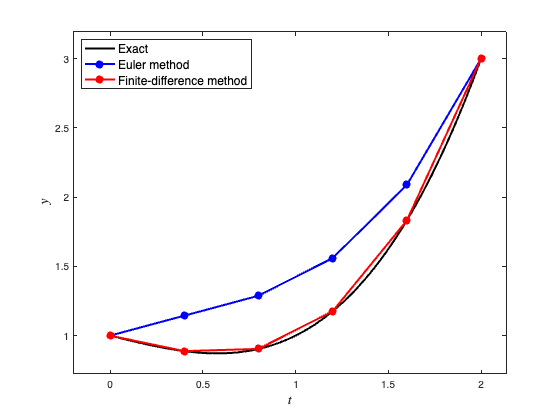

% Define ODE
f = @(t, y) [y(2), 2 * t];

% Define exact solution
exact = @(t) 1 / 3 * t .^ 3 - 1 / 3 * t + 1;

% Define BVP
tspan = [0, 2];
bvals = [1, 3];
h = 0.4;

% Solve BVP using the shooting method
[t, y_euler] = shooting_method(@euler, f, tspan, bvals, h, 1e-4);

% Solve BVP using finite-difference method
n = floor((tspan(2) - tspan(1)) / h) + 1;
t = (0 : n - 1) * h;
a = zeros(n, 1);
b = zeros(n, 1);
c = zeros(n, 1);
d = zeros(n, 1);
b([1, end]) = 1;
d([1, end]) = bvals;
for i = 2 : n - 1
    a(i) = 1;
    b(i) = -2;
    c(i) = 1;
    d(i) = 2 * h ^ 2 * t(i);
end
y_fdm = tridiagonal_solver(a, b, c, d);

% Calculate exact solution
t_exact = linspace(tspan(1), tspan(2), 200);
y_exact = exact(t_exact);

% Plot solutions
plot(t_exact, y_exact, "k", LineWidth=2)
hold on
plot(t, y_euler(:, 1), "b-o", LineWidth=2, MarkerFaceColor="b")
plot(t, y_fdm, "r-o", LineWidth=2, MarkerFaceColor="r")
hold off
axis padded
xlabel("$t$", FontSize=14, Interpreter="latex")
ylabel("$y$", FontSize=14, Interpreter="latex")
legend("Exact", "Euler method", "Finite-difference method", Location="northwest", FontSize=12)

## Functions

#### Euler method

function [t, y] = euler(f, tspan, y0, h)

% Define t and y arrays
t = zeros(10000);
y = zeros(10000, length(y0));
t(1) = tspan(1);
y(1,:) = y0;


% Loop through the steps
n = 1;
while t(n) < tspan(2)

    % Ensure t does not exceed tspan(2)
    h = min(h, tspan(2) - t(n));

    % Calculate Euler method
    y(n+1,:) = y(n,:) + h * f(t(n), y(n,:));
    t(n+1) = t(n) + h;
    n = n + 1;
end

% Remove unused entries from t and y
t(n+1:end) = [];
y(n+1:end,:) = [];

end

#### Tri-diagonal solver

function x = tridiagonal_solver(a, b, c, d)

n = length(b);
for i = 2 : n
    w = a(i) / b(i-1);
    b(i) = b(i) - w * c(i-1);
    d(i) = d(i) - w * d(i-1);
end

x = zeros(n, 1);
x(n) = d(n) / b(n);
for i = n - 1 : -1 : 1
    x(i) = (d(i) - c(i) * x(i+1)) / b(i);
end

end

#### Shooting method

function [t, y] = shooting_method(solver, f, tspan, bvals, h, tol)

s = 1;
sprev = 2;
gprev = 1;
for i = 1 : 10
    [t, y] = solver(f, tspan, [bvals(1), s], h);
    g = bvals(2) - y(end,1);
    temp = s;
    s = s - g * (s - sprev) / (g - gprev);
    sprev = temp;
    gprev = g;
    if abs(s - sprev) < tol
        break
    end
end

end